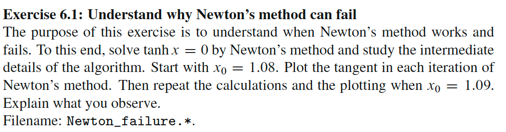

%define function and derivative
f = @(x) tanh(x);            
dfdx = @(x) 1 - tanh(x).^2; 

%initial guess
x0 = 1.08;
tol = 1e-6;      %tolerance
imax = 25;       %max iterations

%initialize variables
x = x0; %current x-value
iteration_data = struct('x', [], 'f', [], 'slope', [], 'intercept', []); %tangent data
iterations = 0;  %iteration counter

%plot
figure;
x_range = linspace(-2, 2, 1000);
y_range = arrayfun(f, x_range);

hold on;
plot(x_range, y_range, 'b', 'LineWidth', 1.5); % Plot function f(x)
plot(x_range, zeros(size(x_range)), 'k--', 'LineWidth', 1); %plot y = 0
xlabel('x'); ylabel('f(x)');
title("Newton's Method Iterations");
legend('f(x)', 'Location', 'Best');

%Simple mplementation of Newton's method
while abs(f(x)) > tol && iterations < imax
    fx = f(x);
    dfx = dfdx(x);

    if abs(dfx) < 1e-15
        fprintf('Error: Derivative too small at x = %.8f\n', x);
        break;
    end

    %store iteration data
    iteration_data.x = [iteration_data.x, x];
    iteration_data.f = [iteration_data.f, fx];
    iteration_data.slope = [iteration_data.slope, dfx];
    iteration_data.intercept = [iteration_data.intercept, fx - dfx * x];

    %plot tangent line
    tangent_y = dfx * x_range + (fx - dfx * x);
    plot(x_range, tangent_y, 'r--', 'LineWidth', 1);
    plot(x, fx, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');

    %add line from y = 0 to (xi, f(xi))
    plot([x, x], [0, fx], 'k--', 'LineWidth', 0.8);

    %update x using Newton's method formula
    x = x - fx / dfx;
    iterations = iterations + 1;

    pause(2.5); %pause for visualization
end

%final result
fprintf('Solution x = %.8f after %d iterations with f(x) = %.8e\n', x, iterations, f(x));

Solution x = -0.00000000 after 7 iterations with f(x) = -9.21053124e-15


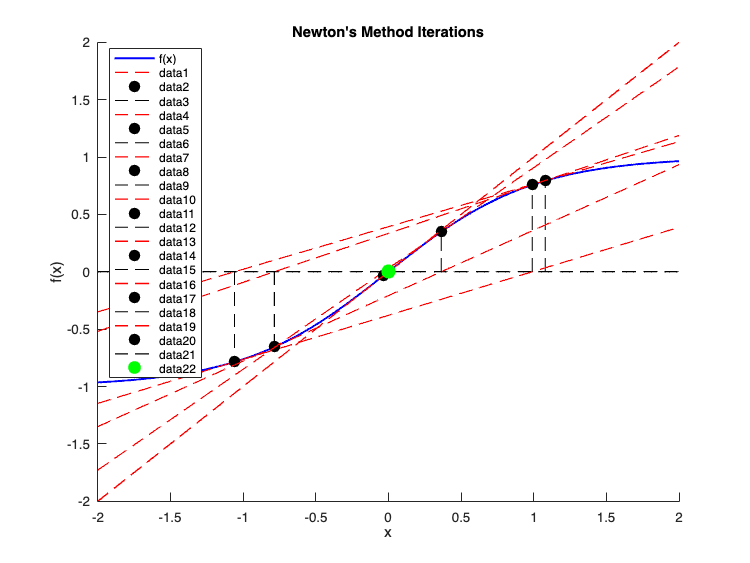


%final plot point
plot(x, 0, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
hold off;